#### Error Rate Analysis

Bit error in various scenarios

- Normal use: leigitimate user hashcode BER

- Intruder: intruder generated hashcode BER

- Intruder2" intruder's own hashcode BER

- Guesser: intruder guess the hashcode

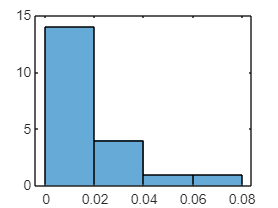

close all;clf
% normal BER
histogram(newUsers_auth_same.ber)

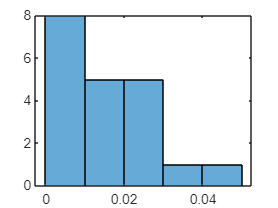

histogram(newUsers_auth_cross.ber)

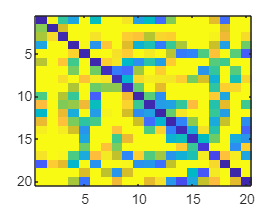

% intruder BER
intruder_ber = zeros(config.user_T_num);
intruder_ber_vec = [];
for i = 1:config.user_T_num
    for j = 1:config.user_T_num
        legit_template = newUsers_enroll.hashcode{i};
        intruder_data = newUsers_auth_same.feature{j};

        % calculate hashcode
        msk = newUsers_enroll.bmask{i};
        Q = newUsers_enroll.randmatrix{i};

        intruder_hs = helper_biohashing_auth(intruder_data .* msk, Q);
        ber = mean(xor(legit_template,intruder_hs),'all');
        intruder_ber(i,j) = ber;
        
        if i~=j
            intruder_ber_vec = [intruder_ber_vec; ber];
        end

    end
end
intruder_ber_vis = intruder_ber/0.5;
intruder_ber_vis(intruder_ber_vis>1) = 1;
imagesc(intruder_ber_vis)

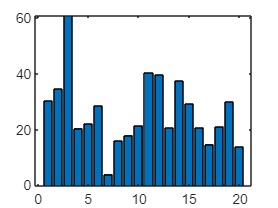

bar(newUsers_enroll.BI)

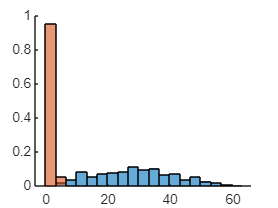


% plot figure
figure;
hold on
binEdges = linspace(0, 63, 20);  % 设置15个bin，范围从0到1
histogram(intruder_ber_vec*63,'Normalization','probability','BinEdges',binEdges);
histogram(newUsers_auth_same.ber*63,'Normalization','probability','BinEdges',binEdges);